% Generated by MATLAB(R) 24.2 (R2024b) and 5G Toolbox 24.2 (R2024b).
% Generated on: 22-Feb-2025 18:25:20

## Generating Downlink waveform

Downlink configuration

cfgDL = nrDLCarrierConfig;
cfgDL.Label = 'DL-FRC-FR1-QPSK';
cfgDL.FrequencyRange = 'FR1';
cfgDL.ChannelBandwidth = 20;
cfgDL.NCellID = 1;
cfgDL.NumSubframes = 10;
cfgDL.InitialNSubframe = 0;
cfgDL.WindowingPercent = [];
cfgDL.SampleRate = [];
cfgDL.CarrierFrequency = 2800000000;

## SCS specific carriers

scscarrier = nrSCSCarrierConfig;
scscarrier.SubcarrierSpacing = 30;
scscarrier.NSizeGrid = 51;
scscarrier.NStartGrid = 0;

cfgDL.SCSCarriers = {scscarrier};

## Bandwidth Parts

bwp = nrWavegenBWPConfig;
bwp.BandwidthPartID = 1;
bwp.Label = 'BWP1';
bwp.SubcarrierSpacing = 30;
bwp.CyclicPrefix = 'normal';
bwp.NSizeBWP = 51;
bwp.NStartBWP = 0;

cfgDL.BandwidthParts = {bwp};

## Synchronization Signals Burst

ssburst = nrWavegenSSBurstConfig;
ssburst.Enable = true;
ssburst.Power = 8;
ssburst.BlockPattern = 'Case B';
ssburst.TransmittedBlocks = [1 1 0 0];
ssburst.Period = 10;
ssburst.NCRBSSB = [];
ssburst.KSSB = 0;
ssburst.DataSource = 'MIB';
ssburst.DMRSTypeAPosition = 2;
ssburst.CellBarred = false;
ssburst.IntraFreqReselection = false;
ssburst.PDCCHConfigSIB1 = 4;
ssburst.SubcarrierSpacingCommon = 30;

cfgDL.SSBurst = ssburst;

## CORESET and Search Space Configuration

CORESET 1

coreset1 = nrCORESETConfig;
coreset1.CORESETID = 1;
coreset1.Label = 'CORESET1';
coreset1.FrequencyResources = ones([1 8]);
coreset1.Duration = 2;
coreset1.CCEREGMapping = 'noninterleaved';
coreset1.REGBundleSize = 6;
coreset1.InterleaverSize = 2;
coreset1.ShiftIndex = 0;
coreset1.PrecoderGranularity = 'sameAsREG-bundle';
coreset1.RBOffset = [];

% CORESET 2
coreset2 = nrCORESETConfig;
coreset2.CORESETID = 0;
coreset2.Label = 'CORESET0';
coreset2.FrequencyResources = ones([1 8]);
coreset2.Duration = 2;
coreset2.CCEREGMapping = 'interleaved';
coreset2.REGBundleSize = 6;
coreset2.InterleaverSize = 2;
coreset2.ShiftIndex = 0;
coreset2.PrecoderGranularity = 'sameAsREG-bundle';
coreset2.RBOffset = [];

cfgDL.CORESET = {coreset1,coreset2};

% Search Spaces
searchspace = nrSearchSpaceConfig;
searchspace.SearchSpaceID = 1;
searchspace.Label = 'SearchSpace1';
searchspace.CORESETID = 1;
searchspace.SearchSpaceType = 'common';
searchspace.StartSymbolWithinSlot = 0;
searchspace.SlotPeriodAndOffset = [1 0];
searchspace.Duration = 1;
searchspace.NumCandidates = [8 8 4 2 1];

cfgDL.SearchSpaces = {searchspace};

## PDCCH Instances Configuration

pdcch = nrWavegenPDCCHConfig;
pdcch.Enable = false;
pdcch.Label = 'PDCCH1';
pdcch.Power = 0;
pdcch.BandwidthPartID = 1;
pdcch.SearchSpaceID = 1;
pdcch.AggregationLevel = 1;
pdcch.AllocatedCandidate = 1;
pdcch.CCEOffset = [];
pdcch.SlotAllocation = [1 2 3 4 5 6 10 11 12 13 14 15 16];
pdcch.Period = 20;
pdcch.Coding = false;
pdcch.DataBlockSize = 20;
pdcch.DataSource = 0;
pdcch.RNTI = 0;
pdcch.DMRSScramblingID = 1;
pdcch.DMRSPower = 0;

cfgDL.PDCCH = {pdcch};

## PDSCH Instances Configuration

pdsch = nrWavegenPDSCHConfig;
pdsch.Enable = true;
pdsch.Label = 'Full-band PDSCH sequence';
pdsch.Power = 18;
pdsch.BandwidthPartID = 1;
pdsch.Modulation = '16QAM';
pdsch.NumLayers = 1;
pdsch.MappingType = 'A';
pdsch.ReservedCORESET = [];
pdsch.SymbolAllocation = [2 12];
pdsch.SlotAllocation = [1 2 3 4 5 6 10 11 12 13 14 15 16];
pdsch.Period = 20;
pdsch.PRBSet = 0:50;
pdsch.PRBSetType = 'VRB';
pdsch.VRBToPRBInterleaving = false;
pdsch.VRBBundleSize = 2;
pdsch.NID = [];
pdsch.RNTI = 1;
pdsch.Coding = true;
pdsch.TargetCodeRate = 0.30078125;
pdsch.TBScaling = 1;
pdsch.XOverhead = 0;
pdsch.LimitedBufferRateMatching = true;
pdsch.MaxNumLayers = 8;
pdsch.MCSTable = 'qam64';
pdsch.RVSequence = 0;
pdsch.DataSource = 'PN9';
pdsch.DMRSPower = 8;
pdsch.EnablePTRS = true;
pdsch.PTRSPower = 10;

% PDSCH Reserved PRB
pdschReservedPRB = nrPDSCHReservedConfig;
pdschReservedPRB.PRBSet = [];
pdschReservedPRB.SymbolSet = [];
pdschReservedPRB.Period = [];

pdsch.ReservedPRB = {pdschReservedPRB};

% PDSCH DM-RS
pdschDMRS = nrPDSCHDMRSConfig;
pdschDMRS.DMRSConfigurationType = 1;
pdschDMRS.DMRSReferencePoint = 'CRB0';
pdschDMRS.DMRSTypeAPosition = 2;
pdschDMRS.DMRSAdditionalPosition = 2;
pdschDMRS.DMRSLength = 1;
pdschDMRS.CustomSymbolSet = [];
pdschDMRS.DMRSPortSet = [];
pdschDMRS.NIDNSCID = [];
pdschDMRS.NSCID = 0;
pdschDMRS.NumCDMGroupsWithoutData = 2;
pdschDMRS.DMRSDownlinkR16 = false;
pdschDMRS.DMRSEnhancedR18 = false;

pdsch.DMRS = pdschDMRS;

% PDSCH PT-RS
pdschPTRS = nrPDSCHPTRSConfig;
pdschPTRS.TimeDensity = 1;
pdschPTRS.FrequencyDensity = 2;
pdschPTRS.REOffset = '00';
pdschPTRS.PTRSPortSet = [];

pdsch.PTRS = pdschPTRS;

cfgDL.PDSCH = {pdsch};

## CSI-RS Instances Configuration

csirs = nrWavegenCSIRSConfig;
csirs.Enable = true;
csirs.Label = 'CSIRS1';
csirs.Power = 20;
csirs.BandwidthPartID = 1;
csirs.CSIRSType = 'nzp';
csirs.CSIRSPeriod = 'on';
csirs.RowNumber = 3;
csirs.Density = 'one';
csirs.SymbolLocations = 0;
csirs.SubcarrierLocations = 0;
csirs.NumRB = 51;
csirs.RBOffset = 0;
csirs.NID = 1;

cfgDL.CSIRS = {csirs};

% Generation
[waveform,info] = nrWaveformGenerator(cfgDL);

Fs = info.ResourceGrids(1).Info.SampleRate; 								 % Specify the sample rate of the waveform in Hz

## Visualize

Spectrum Analyzer

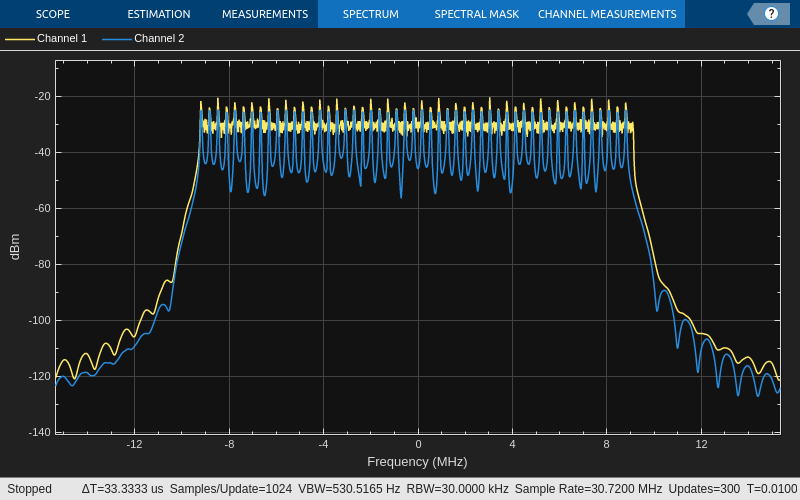

spectrum = spectrumAnalyzer('SampleRate', Fs);
spectrum(waveform);
release(spectrum);

save("vars","cfgDL", "waveform", "info");